# Robot Morphology

Location of RTB robot manipulator models:

.../MatlabDrive/RVC2/rvctools/robot/models

## 6R Robot. Puma 560

Before start the exercise see the videos: 

[https://youtu.be/ArzP7rh4_9Q](https://youtu.be/ArzP7rh4_9Q)

and 

[https://youtu.be/aHV5oY7viBM](https://youtu.be/aHV5oY7viBM)

### Call the robot object and plot it

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


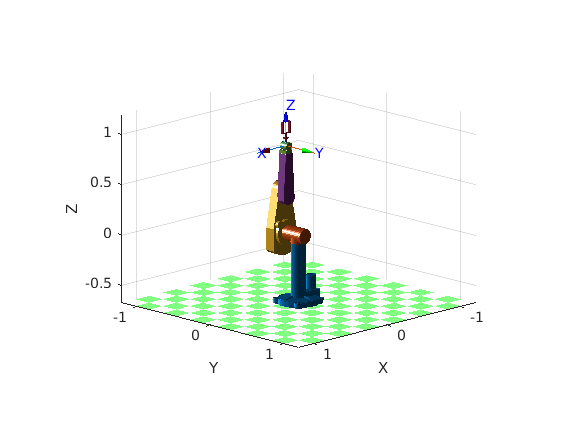

close all
clear
mdl_puma560 % Invoque the puma object
p560.plot3d(qr) % qz is the joint vector 1x6. Try qr, qn, any within the limits

Work with the wire model and change the point of view. 

See: https://es.mathworks.com/help/matlab/creating_plots/setting-the-viewpoint-with-azimuth-and-elevation.html

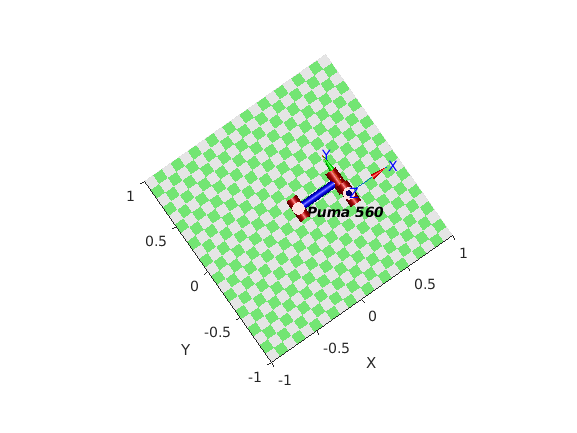

close all
p560.plot(qz)
view([-35 90])

### Play with the teach 

It is a kind of Joystick

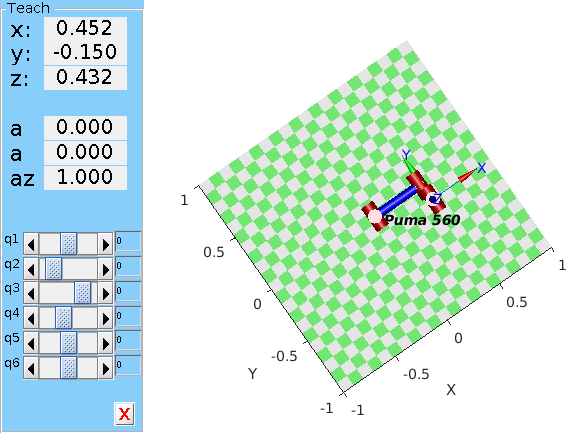

p560.teach('approach')

### Moving the Robot

clear all
close all
mdl_puma560

Declare a joint motion by adding rows

Q=zeros(100,6); % at the moment no motion

See the Joint 1 limits

q1_limits=p560.links(1, 1).qlim

q1_limits =    -2.7925    2.7925


Build the joint's motion. Firts only Joint #1

q1=linspace(q1_limits(1),q1_limits(2),100)';
Q=[q1 Q(:,2:6)]

Q =    -2.7925         0         0         0         0         0
   -2.7361         0         0         0         0         0
   -2.6797         0         0         0         0         0
   -2.6233         0         0         0         0         0
   -2.5669         0         0         0         0         0
   -2.5105         0         0         0         0         0
   -2.4540         0         0         0         0         0
   -2.3976         0         0         0         0         0
   -2.3412         0         0         0         0         0
   -2.2848         0         0         0         0         0


Plotting

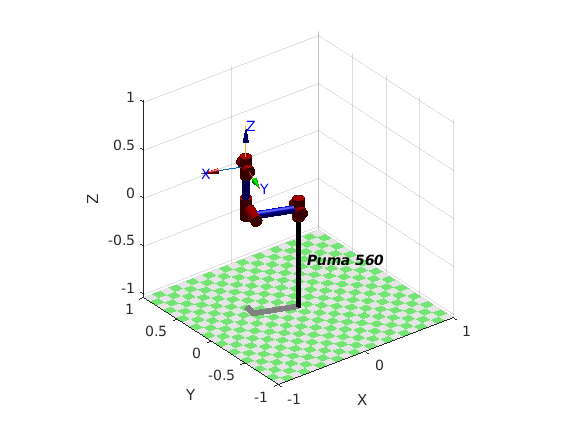

p560.plot(Q)

### Play with the plot options

Moving two joints. See above

q2_limits=p560.links(1, 2).qlim 

q2_limits =    -0.7854    3.9270


q2=linspace(q2_limits(1),q2_limits(2),100)';
Q12=[q1 q2 Q(:,3:6)];

Options: Add a trail to see the trajectory, display the join axis, make biger or smaller the robot

Visit the RTB manual.pdf at:

[https://atenea.upc.edu/pluginfile.php/3871049/mod_resource/content/3/robot.pdf](https://atenea.upc.edu/pluginfile.php/3871049/mod_resource/content/3/robot.pdf)

or

https://petercorke.com/toolboxes/robotics-toolbox/

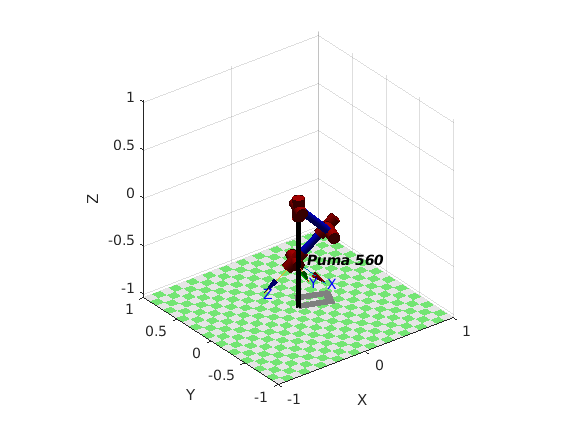

p560.plot(Q12,'trail','--','jaxes','zoom',0.1) %% Play outside the mlx file to see it: copy the setence in Command Window

Play with other options to get familiar with. You must! becouse all along the course it will be necesary

### Recovering End efector position

Use function 'fkine' for recovering the finger tips of the robot

T=p560.fkine(Q12); % Forward Kinematic to be explained. Given Theta's (q's) obtain the robot EE position
ft=[T.t] % to gert only the position

ft =    -0.6386   -0.6335   -0.6251   -0.6135   -0.5990   -0.5817   -0.5618   -0.5397   -0.5155   -0.4896   -0.4623   -0.4340   -0.4048   -0.3753   -0.3456   -0.3163   -0.2875   -0.2596   -0.2329   -0.2077   -0.1843   -0.1629   -0.1437   -0.1270   -0.1128   -0.1013   -0.0927   -0.0869   -0.0840   -0.0841   -0.0869   -0.0926   -0.1009   -0.1118   -0.1250   -0.1404   -0.1576   -0.1766   -0.1970   -0.2184   -0.2407   -0.2635   -0.2864   -0.3092   -0.3316   -0.3531   -0.3735   -0.3924   -0.4097   -0.4250
   -0.0728   -0.1086   -0.1436   -0.1772   -0.2092   -0.2393   -0.2672   -0.2928   -0.3157   -0.3359   -0.3532   -0.3674   -0.3786   -0.3866   -0.3914   -0.3932   -0.3918   -0.3876   -0.3805   -0.3708   -0.3586   -0.3442   -0.3278   -0.3097   -0.2901   -0.2694   -0.2479   -0.2258   -0.2036   -0.1816   -0.1600   -0.1392   -0.1195   -0.1011   -0.0844   -0.0697   -0.0570   -0.0467   -0.0390   -0.0339   -0.0316   -0.0321   -0.0356   -0.0420   -0.0513   -0.0634   -0.0783   -0.0958   -0.1158   -

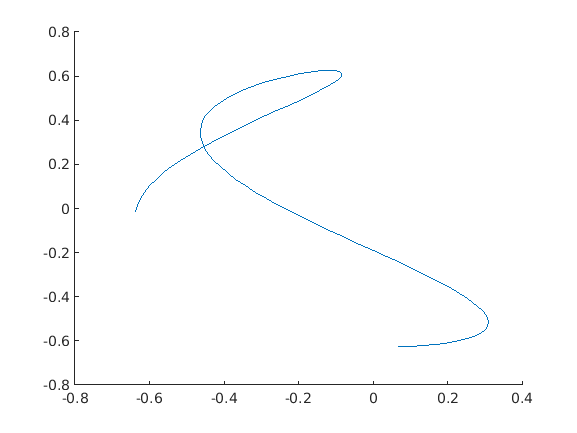

figure
plot3(ft(1,:),ft(2,:), ft(3,:))
view(0,0)

### Working area

clear all
close all
mdl_puma560
q2_limits=p560.links(1, 2).qlim 

q2_limits =    -0.7854    3.9270


q2=linspace(q2_limits(1),q2_limits(2),100)';
Q= [zeros(100,1) linspace(q2_limits(1),q2_limits(2),100)' zeros(100,4) ]

Q =          0   -0.7854         0         0         0         0
         0   -0.7378         0         0         0         0
         0   -0.6902         0         0         0         0
         0   -0.6426         0         0         0         0
         0   -0.5950         0         0         0         0
         0   -0.5474         0         0         0         0
         0   -0.4998         0         0         0         0
         0   -0.4522         0         0         0         0
         0   -0.4046         0         0         0         0
         0   -0.3570         0         0         0         0


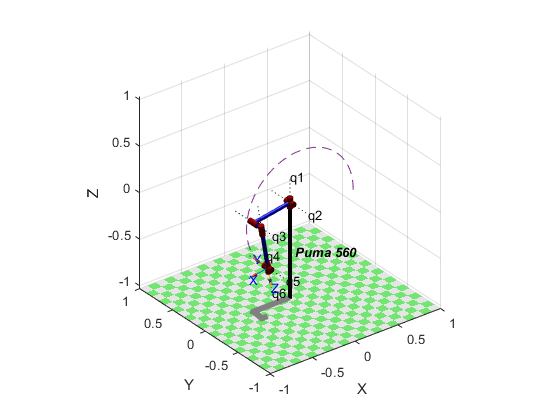

p560.plot(Q,'trail','--','jaxes','zoom',2)

T=p560.fkine(Q);
ft=[T.t]
hold on
v = [-1 -0.1501 -1 ; 1 -0.1501 -1 ; 1 -0.1501 1; -1 -0.1501 1];
f = [1 2 3 4];
patch('Faces',f,'Vertices',v,'FaceColor','blue','FaceAlpha',.3)

## IRB140 exercise

Make the same exercise for the irb140 manipulator and plot the working area as shown in the figure

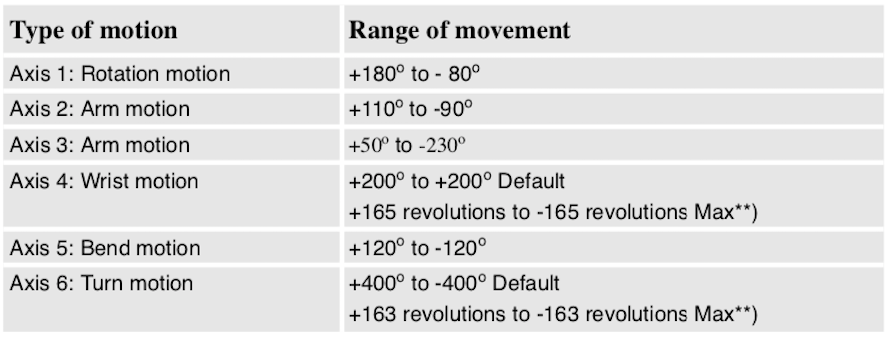

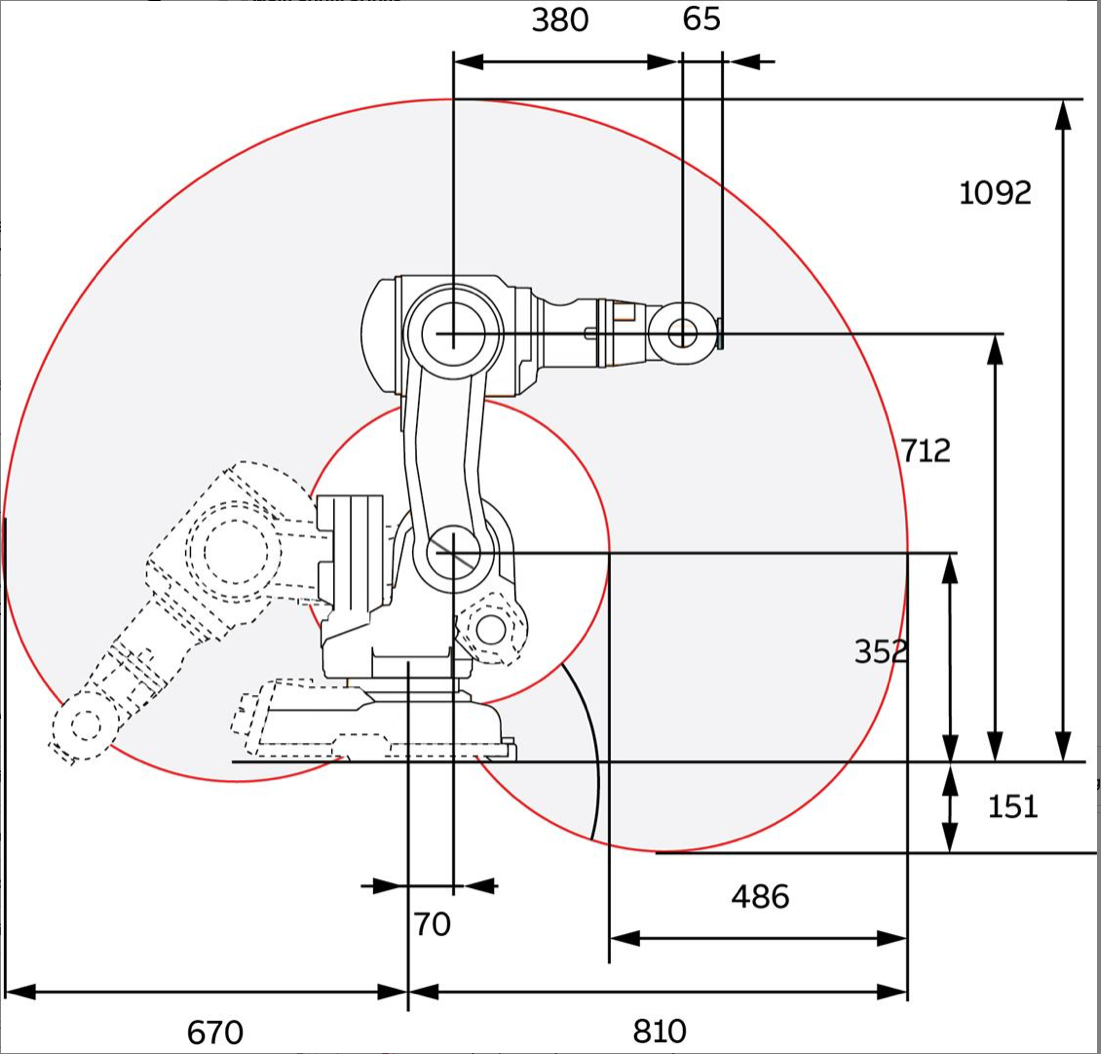

### Invoque IRB140 

clear
close all
mdl_irb140

 
robot = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


### Plot the IRB

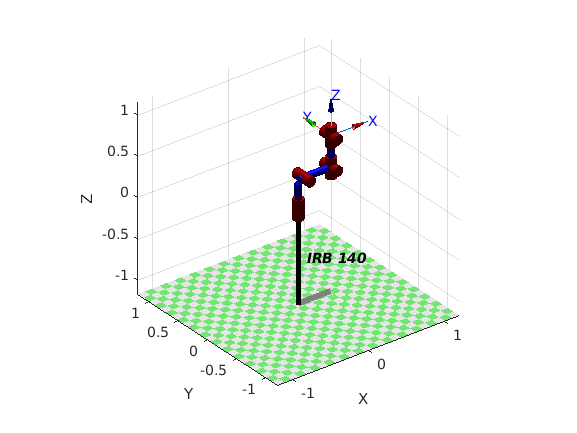

irb140.plot(qz)